Homework #2, Harrison Robel

clear all; close all;

## Problem 1: Brain Teaser

### A little introductory brain teaser. Which is more probable when rolling 2 six-sided dice: rolling snake eyes (two ones) or rolling sevens (dice sum to seven)? What is the ratio of the probabilities?

Probability of rolling snake eyes: There is only one way of rolling snake eyes which is two 1's therefore the probability of rolling snake eyes is 1/6 * 1/6 = 1/36

Probability of rolling a seven: There are six ways too roll a seven with 36 different ways to roll a die there is a 6/36 = 1/6 chance of rolling a seven.

The ratio of rolling snake eyes to rolling a seven is r = (1/36 / 1/6) = 1/6

## Problem 2: Convolution Operator

### Following what we did in class show how to use the convolution operator to determine the probability of the **sum** of 2 six sided dice. Do both analytically (math & counting) and numerically (computer program). Beware the *implicit* definition of the values (x-axis on histogram).

To find the probability that two die sum up to given number is given by the convolution between the two probability functions. The probability functions for a six sided die is just P(x) = 1/6 because each value has an equally as likely chance of being rolled and there are six sides. To do this by counting you simply make a histogram of the probabilities in this case [1,2,3,4,5,6] and run the same list but in reverse direction [6,5,4,3,2,1] the probability of rolling a sum of dice is how many numbers overlap so for summing to 3 you overlap [1,2] with [2,1] and multiply how many overlap with each other then multiply that number with 1/36. To do this with an integral simply integrate the function A(x) (B(x) - z) = (1/6 * (1/6 - z)). 

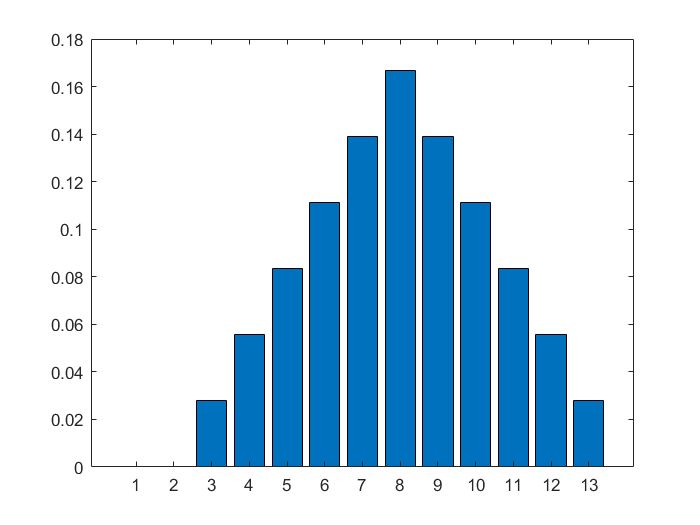

d6 = [0,1,1,1,1,1,1]' / 6;
d6x2 = conv(d6,d6);

bar(d6x2)

## Problem 3: Average

### Calculate the mean and the variance of the distribution in problem 2. Hint: this is surprisingly tricky, make sure your result makes sense.

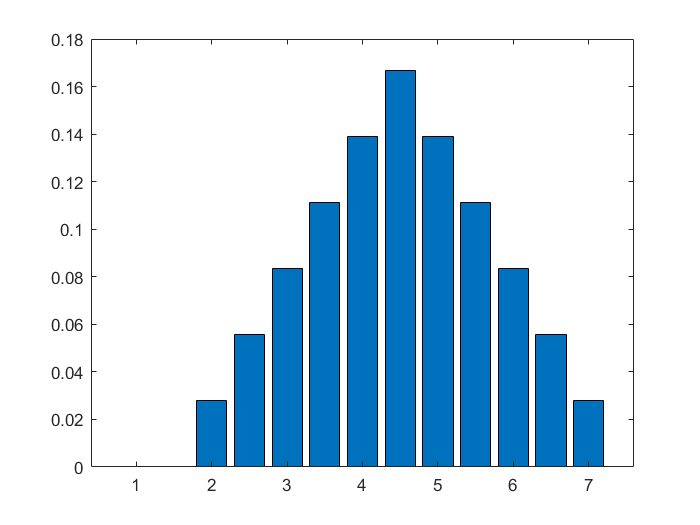

d6 = [0,1,1,1,1,1,1]' / 6;
d6x2 = conv(d6,d6);

cx = 1:(1/2):7;
bar(cx,d6x2)

V = var(d6x2)

V = 0.0030

## Problem 4: 10 Dice

### Repeat 2, and graph the **average** of 10 dice. Is this is a Gaussian distribution? Explain in depth.

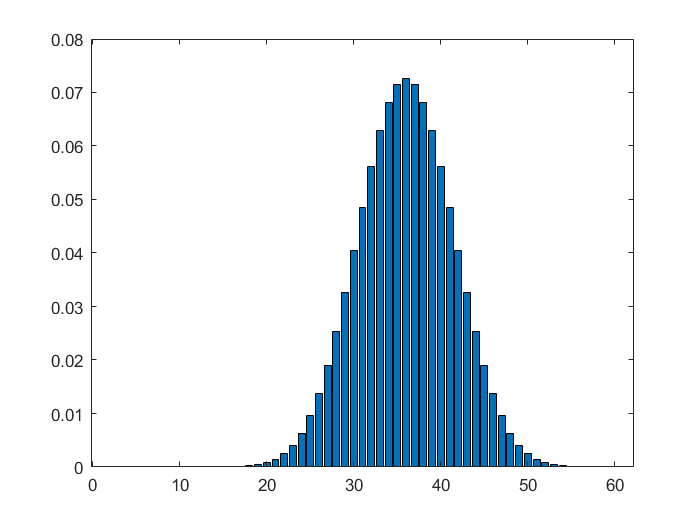

d6 = [0,1,1,1,1,1,1]' / 6;
d6x2 = conv(d6,d6);
d6x4 = conv(d6x2,d6x2);
d6x5 = conv(d6x4,d6);
d6x9 = conv(d6x5,d6x4);
d6x10 = conv(d6x9,d6);

bar(d6x10)

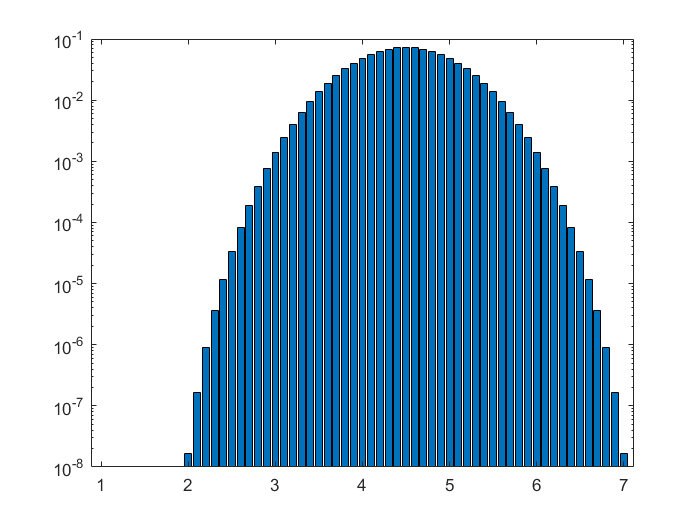


d6 = [0,1,1,1,1,1,1]' / 6;
d6x2 = conv(d6,d6);
d6x4 = conv(d6x2,d6x2);
d6x5 = conv(d6x4,d6);
d6x9 = conv(d6x5,d6x4);
d6x10 = conv(d6x9,d6);

cx = 1:(1/10):7;
bar(cx,d6x10)
set(gca,'YScale','log')

V = var(d6x10)

V = 5.9042e-04

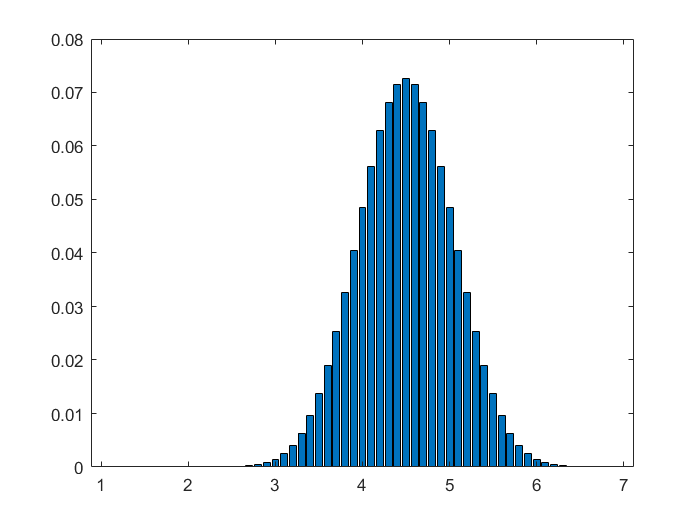

bar(cx,d6x10)

The bar graph for the convolution of 10d6 does tend to be Gaussian distributed based both off of the semi-log plot and the linear plot. Conceptually this makes sense because there is an equal chance of rolling a 1 through 6 on any given die and therefore the distribution of numbers from a die would be normally distributed.

## Problem 5: Gaussian PDF

### Show that the sum and average of an initially Gaussian distribution is also a Guassian (can be analytic or numerical). How does the standard deviation of the resulting sum or average Guassian change? This is a *hugely* important result. Explore what this means for integrating a signal over time.

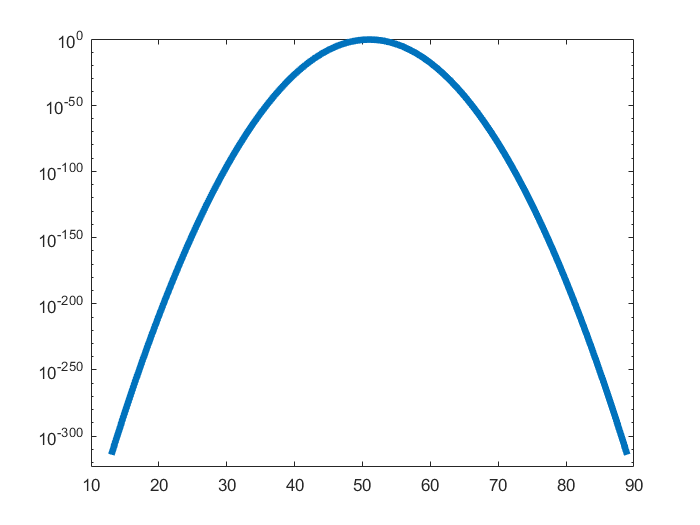

G = normpdf(-50:50,0,1);
plot(G,'LineWidth',4)
set(gca,'Yscale','log')

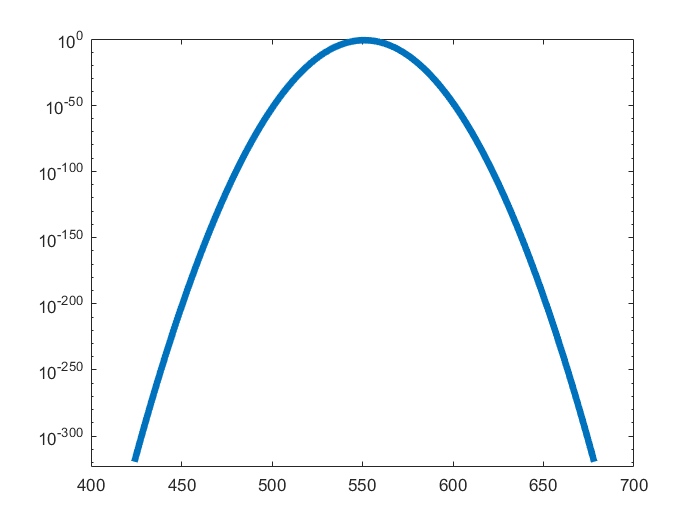


C = G;
for i = 1:10
    C = conv(C,G);
end
plot(C,'LineWidth',4)
set(gca,'Yscale','log')

After convoluting the normal pdf with it's self mulitple times the distribution still appears to be Gaussian, however the width of the plot becomes much larger and the standard deviation increases. As you integrate a signal over time the distribution will blow up and become much larger. The fact that the Guassians get summed together means that the standard deviation of the convoluted pdfs should be the sum of all the standard deviations. In this case I summed 10 together with a standard deviation of 1 so the overall standard deviation will be 10.